Utworzenie funkcji symbolicznej

clearvars   % Czyszczenie śmieci
px = [-10 -5 0 5 10];
py = [0.0001 -0.1 0 0.1 -0.0001];
stopien=5;
W = polyfit(px, py, stopien);

fun=@(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x;   % Definicja funkcji

Wyświetlenie wykresu funkcji

figure
fplot(fun,[-10,10])

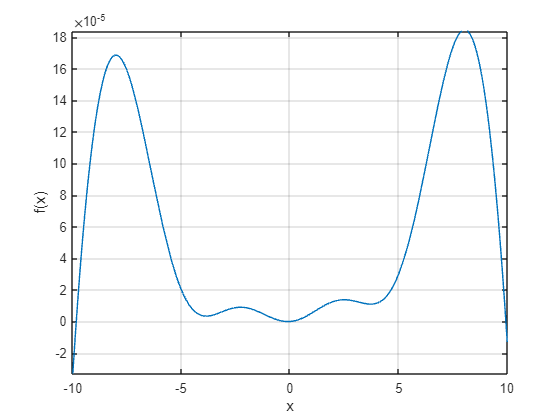

xlabel("x")
ylabel("f(x)")
grid on
hold on

**Wyświetlenie przedziału na wykresie**

%a=1.5 (współczynnik ekspansji)
%x(0)=-8 punkt startowy
%k1=0.1
[xp,xk,i_,x_] = ekspansja_method(-8,0.1,fun,1.5,50);
figure
hold on

fplot(fun,[-9,-2])

fplot(fun,[xp,xk],"g","LineWidth",2)

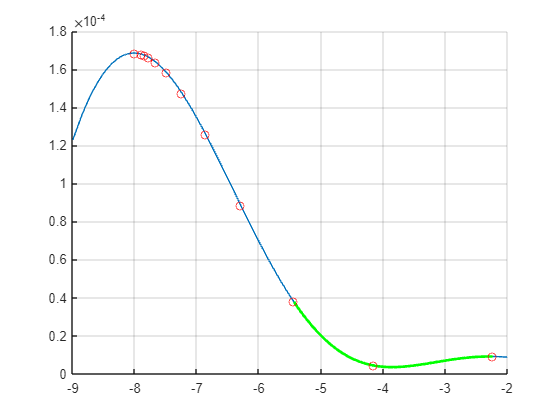

grid on
for i = x_
    plot(i, fun(i), "or")
end
hold off

disp(['xp: ', num2str(xp), ' xk: ', num2str(xk), ' ilość kroków:' num2str(i_) ])

xp: -5.4371 xk: -2.2335 ilość kroków:11


%kontrakcja dla punktu startowego x(0)=-8
%współczynnik alfa przyjmuje a=0.95
[xp,xk,i_,x_] = kontrakcja(xp,xk,fun,0.95,50);
figure
hold on
fplot(fun,[-9,-2])

fplot(fun,[xp,xk],"g","LineWidth",2)

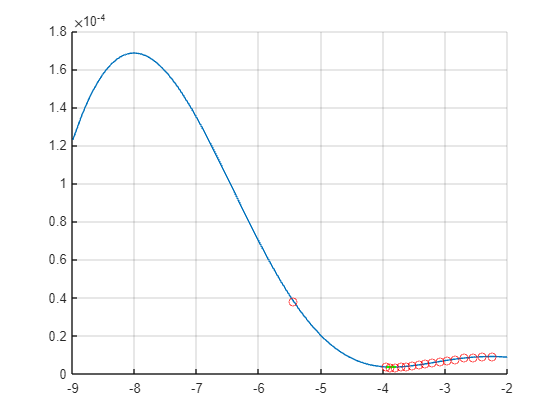

grid on
for i = x_
    plot(i, fun(i), "or")
end
hold off

disp(['xp: ', num2str(xp), ' xk: ', num2str(xk), ' ilość kroków:' num2str(i_) ])

xp: -3.9529 xk: -3.7926 ilość kroków:16


%a=1.5 (współczynnik ekspansji)
%x(0)=-0.5 punkt startowy
%k1=0.1
[xp,xk,i_,x_] = ekspansja_method(-0.5,0.1,fun,1.5,50);
figure
hold on

fplot(fun,[-0.6,0.2])

fplot(fun,[xp,xk],"g","LineWidth",2)

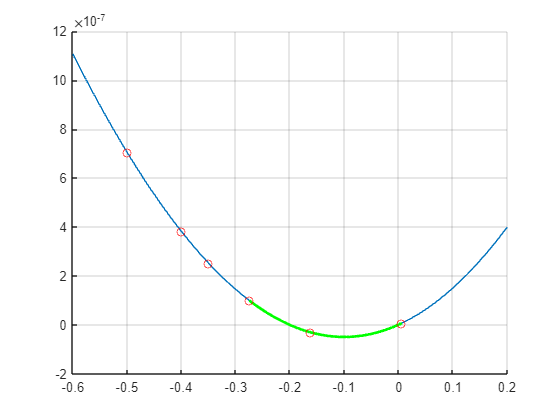

grid on
for i = x_
    plot(i, fun(i), "or")
end
hold off

disp(['xp: ', num2str(xp), ' xk: ', num2str(xk), ' ilość kroków:' num2str(i_) ])

xp: -0.275 xk: 0.00625 ilość kroków:5


%kontrakcja dla punktu startowego x(0)=-0.5
%współczynnik alfa przyjmuje a=0.95
[xp,xk,i_,x_] = kontrakcja(xp,xk,fun,0.95,50);
figure
hold on
fplot(fun,[-0.6,0.2])

fplot(fun,[xp,xk],"g","LineWidth",2)

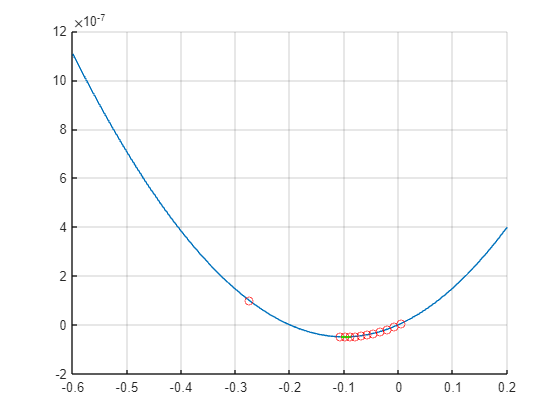

grid on
for i = x_
    plot(i, fun(i), "or")
end
hold off

disp(['xp: ', num2str(xp), ' xk: ', num2str(xk), ' ilość kroków:' num2str(i_) ])

xp: -0.10661 xk: -0.088413 ilość kroków:11


%a=1.5 (współczynnik ekspansji)
%x(0)=1 punkt startowy
%k1=0.1
[xp,xk,i_,x_] = ekspansja_method(1,0.1,fun,1.5,50);
figure
hold on

fplot(fun,[-1,2])

fplot(fun,[xp,xk],"g","LineWidth",2)

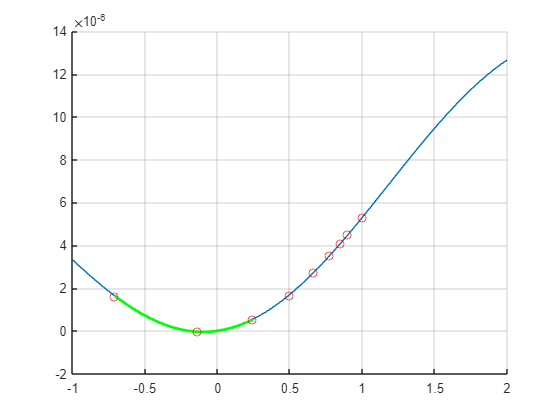

grid on
for i = x_
    plot(i, fun(i), "or")
end
hold off

disp(['xp: ', num2str(xp), ' xk: ', num2str(xk), ' ilość kroków:' num2str(i_) ])

xp: -0.70859 xk: 0.24062 ilość kroków:8


%kontrakcja dla punktu startowego x(0)=1
%współczynnik alfa przyjmuje a=0.95
[xp,xk,i_,x_] = kontrakcja(xp,xk,fun,0.95,50);
figure
hold on
fplot(fun,[-0.8,0.6])

fplot(fun,[xp,xk],"g","LineWidth",2)

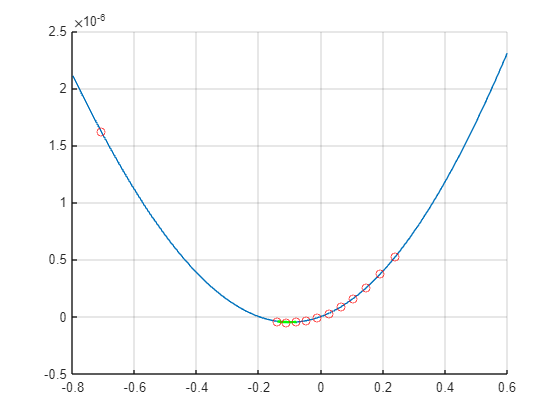

grid on
for i = x_
    plot(i, fun(i), "or")
end
hold off

disp(['xp: ', num2str(xp), ' xk: ', num2str(xk), ' ilość kroków:' num2str(i_) ])

xp: -0.14026 xk: -0.078863 ilość kroków:11


%a=1.5 (współczynnik ekspansji)
%x(0)=8 punkt startowy
%k1=0.1
[xp,xk,i_,x_] = ekspansja_method(8,0.1,fun,1.5,50);
figure
hold on

fplot(fun,[5,40])

fplot(fun,[xp,xk],"g","LineWidth",2)

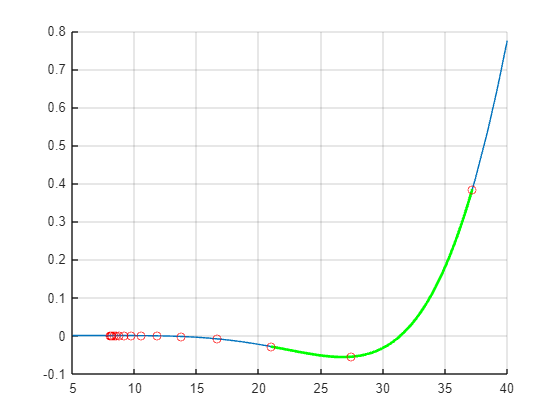

grid on
for i = x_
    plot(i, fun(i), "or")
end
hold off

disp(['xp: ', num2str(xp), ' xk: ', num2str(xk), ' ilość kroków:' num2str(i_) ])

xp: 20.9746 xk: 37.1929 ilość kroków:15


%kontrakcja dla punktu startowego x(0)=8
%współczynnik alfa przyjmuje a=0.95
[xp,xk,i_,x_] = kontrakcja(xp,xk,fun,0.95,50);
figure
hold on
fplot(fun,[5,40])

fplot(fun,[xp,xk],"g","LineWidth",2)

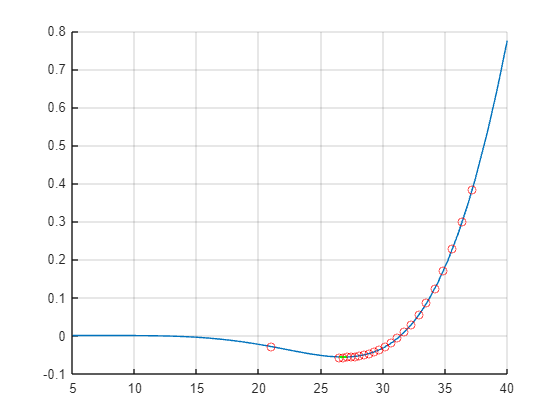

grid on
for i = x_
    plot(i, fun(i), "or")
end
hold off

disp(['xp: ', num2str(xp), ' xk: ', num2str(xk), ' ilość kroków:' num2str(i_) ])

xp: 26.498 xk: 27.0947 ilość kroków:22


function [x_0,x_1,i,x] = ekspansja_method(x0,krok_pocz,fun,alfa,Nmax)


x = [x0,x0];

x_l = x(1) - krok_pocz; % krok w lewo
x_p = x(1) + krok_pocz; % krok w prawo

x(1) = x0;
x(2) = x_p;

if fun(x_p) == fun(x(1))
    x_0 = x0;
    x_1 = x_p;
    i = 1;
    return
end

if fun(x_p) > fun(x(1))
    x(1) = x0;
    x(2) = x_l;
    krok_pocz = -krok_pocz;
    if fun(x_l) > fun(x(1))
        x_0 = x_l;
        x_1 = x_p;
        i = 1;
    return
    end
end
i = 1;

while fun(x(i)) > fun(x(i+1))
    i = i+1;
    if i > Nmax
        error("Przekroczono liczbe iteracji")
    end    

    x(i+1) = (alfa ^ (i-1))* krok_pocz + x0;
end

if x(i-1) < x(i+1)
    x_0 = x(i-1);
    x_1 = x(i+1);
    return
else
    x_0 = x(i+1);
    x_1 = x(i-1);
    return
end

end

function [x_0,x_1,i,x] = kontrakcja(x0,x1,fun,alfa,Nmax)

x = [x0,x1];
i=1;

x(1) = x1;
while fun(x(i)) >= fun(x(i+1))
    i = i+1;
    x(i+1) = x0 + (x1-x0)*(alfa^(i-1));
    if i > Nmax
        error("Przekroczono liczbe iteracji")
    end    
end
x(1) = x0;


if x(i-1) < x(i+1)
    x_0 = x(i-1);
    x_1 = x(i+1);
    return
else
    x_0 = x(i+1);
    x_1 = x(i-1);
    return
end

end